# Serial-link manipulator Jacobian matrix

Copyright (C) 1993-2018, by Peter I. Corke, [http://www.petercorke.com](http://www.petercorke.com)

## Simple plotting and animation

We will work with a model of the Puma 560 robot

mdl_puma560

The trajectory demonstration has shown how a joint coordinate trajectory may be generated

t = [0:.05:2]'; 	% generate a time vector
q = jtraj(qz, qr, t); % generate joint coordinate trajectory

the overloaded function plot() animates a stick figure robot moving along a trajectory.

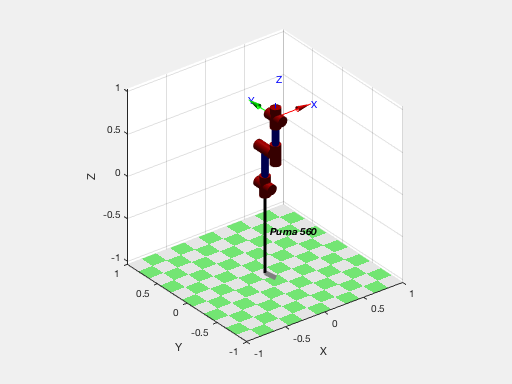

clf; p560.plot(q);

The drawn line segments do not necessarily correspond to robot links, but join the origins of sequential link coordinate frames.  The plot also includes:

- A small right-angle coordinate frame is drawn on the end of the robot to show the wrist orientation.

- A shadow appears on the ground which helps to give some better idea of the 3D object.

This is a 3D plot so using the tools on the figure toolbar you can rotate the figure and change your viewpoint.

## Interactively drive the graphical robot

Sometimes it's useful to be able to manually drive the robot around to get an understanding of how it works.

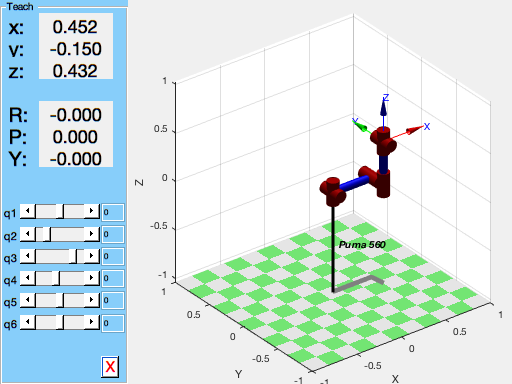

clf; p560.teach()

Use the sliders to control the robot (in fact both views).  Hit the red X button when you are done. You can find the final joint angles of the robot you drove it to

p560.getpos()

ans =      0     0     0     0     0     0


## Plotting multiple robots in the same plot

We can place multiple robots into a single figure.  We plot the original robot

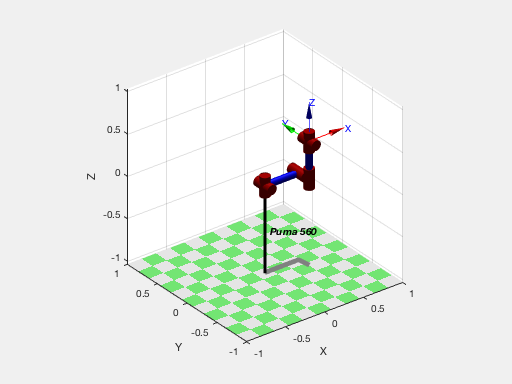

clf; p560.plot(qz)

Let's make a clone of the Puma robot, but change its name and base location

p560_2 = SerialLink(p560, 'name', 'another Puma', 'base', transl(-0.5, 0.5, 0) )

 
p560_2 = 
 
another Puma [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE        
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-0.5, 0.5, 0), RPY/xyz = (0, 0, 0) deg             
 


We turn hold on so that the new robot doesn't erase the existing one, then plot it

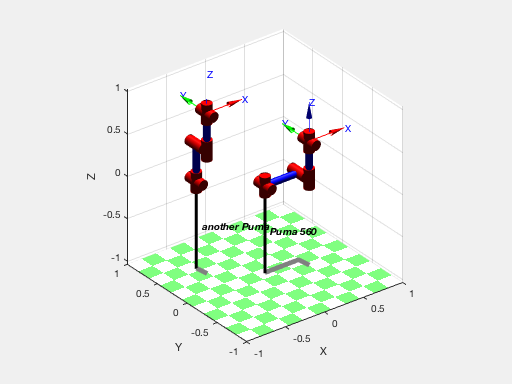

hold on
p560_2.plot(q);

## Plotting multiple simultaneous views

We can also have multiple views of the same robot.  First clear the plot and show one robot

clf
subplot(121)
p560.plot(qr);

Then create another plot and plot the robot again, but with a different view angle

subplot(122)
p560.plot(qr);
view(40,50)

so now when we animate the robot, it moves in both views

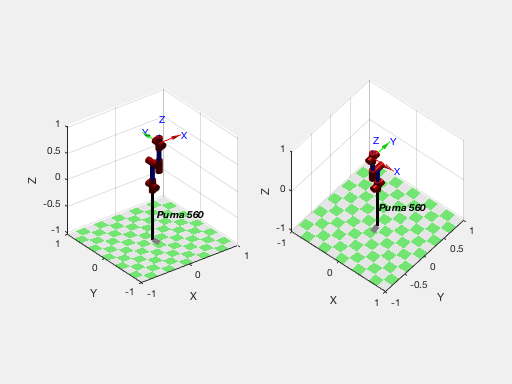

p560.plot(q)

## Fully rendered 3D plotting

For some standard robot models there are full 3D models (defined by STL files, 1 per joint).  The first time you run this there will be a short delay as the model files are read in.

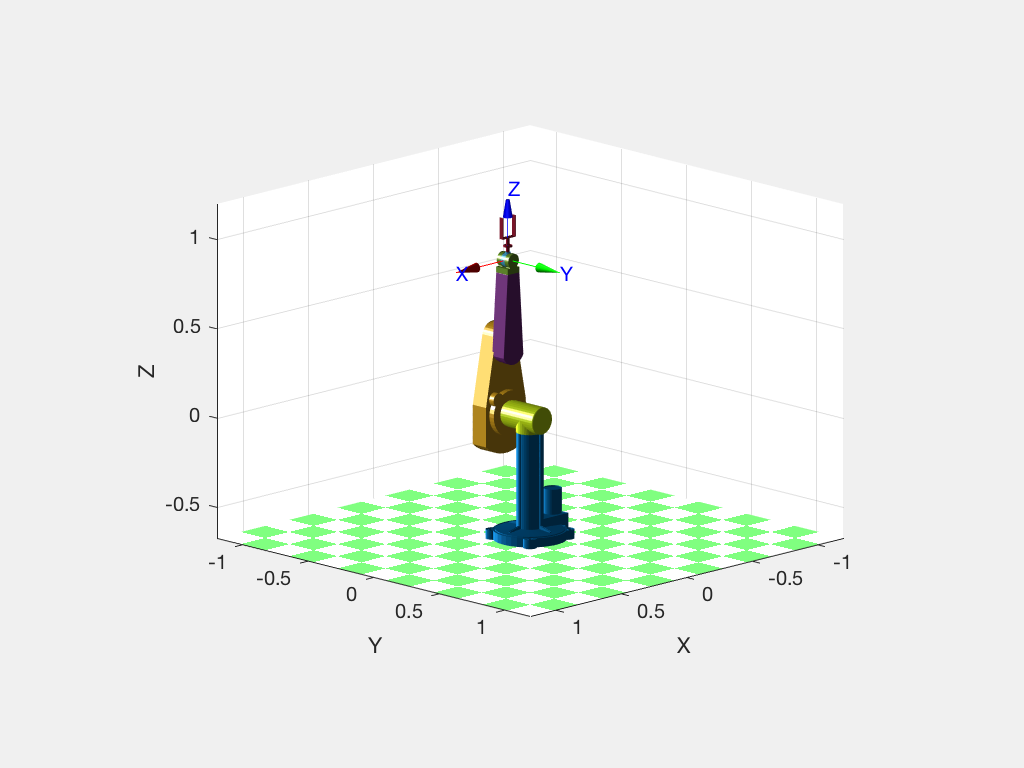

clf; p560.plot3d(q)